%% ============================================================
%       RIS 4x4 ARRAY VALIDATION - STREAMLINED
%  Purpose: Exhaustive optimization for 1-bit 4x4 RIS,
%  extracting only critical beamforming metrics and matrix configs.
% =============================================================

clear; clc; close all;

%% 1. CORE PARAMETERS & HFSS DATA
f = 2.45e9;                 
c = 299792458;              
lambda = c/f;               
k = 2*pi/lambda;            
pitch_mm = 61;               
d = pitch_mm/1000;           

% HFSS Unit Cell Values
phaseON  = 148.9220;
phaseOFF = -70.2555;
magON  = 10^(-1.4661/20);
magOFF = 10^(-1.3114/20);

arrayN = 4;
numElements = arrayN^2;
numConfigurations = 2^numElements;
targetAngles = 0:10:60; % Streamlined to 10-deg steps for clean reporting
theta = -90:0.1:90;

% Element Coordinates
[x,y] = meshgrid(((0:arrayN-1) - (arrayN-1)/2)*d, ((0:arrayN-1) - (arrayN-1)/2)*d);
x = x(:); y = y(:);

% Array Factor Anonymous Function
arrayFactor = @(state) calculateAF(state, x, k, d, theta, phaseON, phaseOFF, magON, magOFF);

%% 2. EXHAUSTIVE OPTIMIZATION LOOP
numTargets = length(targetAngles);
bestBeam = nan(numTargets,1);
bestError = nan(numTargets,1);
bestSLL = nan(numTargets,1);
bestConfig = cell(numTargets,1);
bestPattern = cell(numTargets,1);

fprintf('Running exhaustive search across %d configurations...\n', numConfigurations);

Running exhaustive search across 65536 configurations...



for t = 1:numTargets
    target = targetAngles(t);
    bestScore = -inf;
    
    for configNumber = 0:(numConfigurations-1)
        bits = bitget(configNumber, 1:numElements)';
        AF = arrayFactor(bits);
        
        P = abs(AF);
        P = P/max(P);
        PdB = 20*log10(P + 1e-12);
        
        [~,idxGlobal] = max(P);
        globalBeam = theta(idxGlobal);
        error = globalBeam - target;
        
        if abs(error) <= 10
            HPBW = calculateHPBW(theta, PdB, idxGlobal);
            SLL = calculateSLL(theta, PdB, idxGlobal, HPBW);
            
            % Scoring metric: prioritize steering accuracy, penalize high SLL
            score = -100*abs(error) - 0.2*max(SLL, -50);
            
            if score > bestScore
                bestScore = score;
                bestBeam(t) = globalBeam;
                bestError(t) = error;
                bestSLL(t) = SLL;
                bestPattern{t} = PdB;
                bestConfig{t} = reshape(bits, arrayN, arrayN);
            end
        end
    end
    % Fallback if no config meets criteria (highly unlikely for small angles)
    if isinf(bestScore)
         bestBeam(t) = NaN; bestError(t) = NaN; bestSLL(t) = NaN;
    end
end

%% 3. FINAL RESULTS TABLE & CONFIGURATIONS
fprintf('\n============================================================\n');

fprintf('                 FINAL 4x4 RESULTS\n');

                 FINAL 4x4 RESULTS


fprintf('============================================================\n');

fprintf(' Target   Beam      Error      SLL\n');

 Target   Beam      Error      SLL


fprintf('  (deg)   (deg)     (deg)      (dB)\n');

  (deg)   (deg)     (deg)      (dB)


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for t = 1:numTargets
    fprintf('%7.1f %8.2f %9.2f %10.2f\n', targetAngles(t), bestBeam(t), bestError(t), bestSLL(t));
end

    0.0     0.00      0.00      -3.09
   10.0    10.00      0.00      -2.55
   20.0    18.10     -1.90      -2.11
   30.0    34.50      4.50       0.00
   40.0    40.00      0.00       0.00
   50.0    49.60     -0.40        NaN
   60.0    59.10     -0.90        NaN



fprintf('\n============================================================\n');

fprintf('              HFSS-READY MATRICES (1=ON, 0=OFF)\n');

              HFSS-READY MATRICES (1=ON, 0=OFF)


fprintf('============================================================\n');

for t = 1:numTargets
    fprintf('\nTarget = %+5.1f deg (Actual Beam: %+5.1f deg)\n', targetAngles(t), bestBeam(t));
    disp(bestConfig{t});
end


Target =  +0.0 deg (Actual Beam:  +0.0 deg)


     1     1     1     1
     1     0     1     1
     1     1     1     1
     1     1     0     1




Target = +10.0 deg (Actual Beam: +10.0 deg)


     0     0     1     1
     0     1     1     1
     0     0     1     0
     1     0     0     0




Target = +20.0 deg (Actual Beam: +18.1 deg)


     0     0     1     1
     0     0     1     1
     0     0     1     1
     0     0     1     1




Target = +30.0 deg (Actual Beam: +34.5 deg)


     1     1     1     0
     0     1     1     0
     0     1     1     1
     0     1     1     0




Target = +40.0 deg (Actual Beam: +40.0 deg)


     0     1     1     0
     0     1     1     0
     0     1     1     0
     0     0     0     0




Target = +50.0 deg (Actual Beam: +49.6 deg)


     1     1     0     1
     1     1     0     1
     1     1     0     1
     0     1     0     0




Target = +60.0 deg (Actual Beam: +59.1 deg)


     1     1     0     1
     1     1     0     1
     0     1     0     1
     0     0     0     0



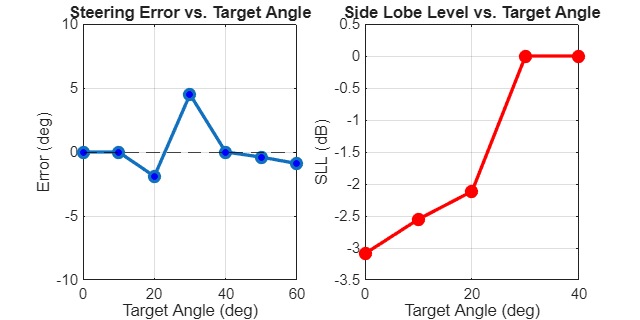


%% 4. ESSENTIAL PLOTS
% Figure 1: Steering Performance Summary
figure('Name','4x4 RIS Performance Metrics','Position',[100 100 800 400]);
subplot(1,2,1);
plot(targetAngles, bestError, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
yline(0, 'k--'); grid on;
title('Steering Error vs. Target Angle');
xlabel('Target Angle (deg)'); ylabel('Error (deg)');
ylim([-10 10]);

subplot(1,2,2);
plot(targetAngles, bestSLL, '-ro', 'LineWidth', 2, 'MarkerFaceColor', 'r');
grid on;
title('Side Lobe Level vs. Target Angle');
xlabel('Target Angle (deg)'); ylabel('SLL (dB)');

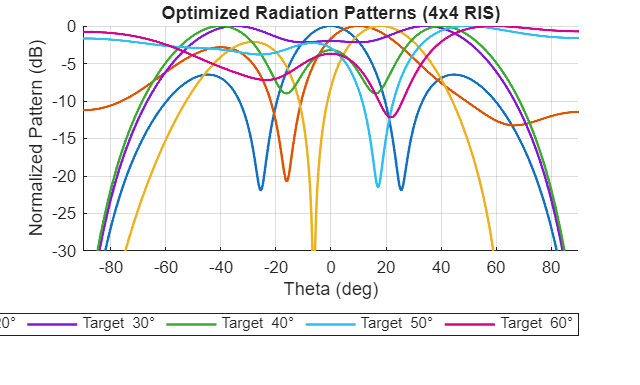


% Figure 2: Selected Radiation Patterns
figure('Name','Radiation Patterns');
hold on; grid on;
colors = lines(numTargets);
for t = 1:numTargets
    if ~isnan(bestBeam(t))
        plot(theta, bestPattern{t}, 'LineWidth', 1.5, 'Color', colors(t,:), ...
            'DisplayName', sprintf('Target %d\\circ', targetAngles(t)));
    end
end
title('Optimized Radiation Patterns (4x4 RIS)');
xlabel('Theta (deg)'); ylabel('Normalized Pattern (dB)');
ylim([-30 0]); xlim([-90 90]);
legend('Location', 'southoutside', 'Orientation', 'horizontal');


%% ============================================================
% HELPER FUNCTIONS
% =============================================================

function AF = calculateAF(state, x, k, d, theta, phaseON, phaseOFF, magON, magOFF)
    phase = zeros(size(state));
    mag = zeros(size(state));
    
    phase(state == 1) = deg2rad(phaseON);
    phase(state == 0) = deg2rad(phaseOFF);
    mag(state == 1) = magON;
    mag(state == 0) = magOFF;
    
    AF = zeros(size(theta));
    for n = 1:length(theta)
        th = deg2rad(theta(n));
        steeringPhase = k * x * sin(th);
        AF(n) = sum(mag .* exp(1j*(phase + steeringPhase)));
    end
end

function HPBW = calculateHPBW(theta, PdB, idxPeak)
    level = -3;
    left = idxPeak; right = idxPeak;
    while left > 1 && PdB(left) >= level, left = left - 1; end
    while right < length(PdB) && PdB(right) >= level, right = right + 1; end
    if left == 1 || right == length(PdB), HPBW = NaN; else, HPBW = theta(right) - theta(left); end
end

function SLL = calculateSLL(theta, PdB, idxPeak, HPBW)
    if isnan(HPBW), SLL = NaN; return; end
    peakAngle = theta(idxPeak);
    exclusion = abs(theta - peakAngle) <= HPBW/2;
    sidelobes = PdB(~exclusion);
    if isempty(sidelobes), SLL = NaN; else, SLL = max(sidelobes); end
end